# Chi-squared distribution

Statistical models are checked for how well they fit data using a variety of goodness-of-fit tests. The chi-squared distribution figures prominently in tests of whether data come from a Gaussian distribution. In machine learning, a very different approach is used to check how well models fit the data, namely, they use the mean-squared-error for a test data set. To be able to contrast the statistical and machine learning approaches, let's see how to use the chi-squared distribution as an example of a statistical approach.

The chi-squared distribution is a family of distributions, $\chi^2_k$, with each member defined by the number of degrees of freedom, $k$.

The square of a random variable with a Gaussian distribution has a chi-squared distribution with 1 degree of freedom. In other words, if


$$x \sim N(0,1)$$


then


$$x^2 \sim \chi^2_1$$


There is 1 degree of freedom because each sample is of size 1. 

To make the above clear, let's plot a normalized histogram of $x^2$ and compare it to the probability density function of $\chi^2_1$.

Generate a large number of samples of size 1 from a Gaussian distribution with mean zero. We use a large number of samples in order to plot a good histogram.

ns = 1000000;         % number of samples
x  = randn(ns,1);     % samples from Gaussian distribution
d  = x.*x;            % samples from chi-squared distribution

Compute and plot a normalized histogram of $x^2$.

c = 0:0.2:8;          % bin centers
f = hist(d,c)/ns/0.2;
clf
plot(c,f,'bo');
hold on

Overlay a plot of the chi-squared probability density function, with 1 degree of freedom. Observe that the normalized histogram and the probability density function match very closely.

y = chi2pdf(c,1);
p1 = plot(c,y,'b-');
ylim([0 .5]);

### Degrees of freedom of the chi-squared distribution

In the previous example, the sample size is 1, so the chi-squared distribution is the one with 1 degree of freedom. Now consider a sample of $n$ observations from a standard normal distribution, $x_1, \ldots, x_n$. The sum of squares of the $n$ observations has a chi-squared distribution with $m$ degrees of freedom

$x_1^2 + x_2^2 + \cdots + x_n^2 \sim \chi^2_n$.

We repeat the example above, now with a sample size of $n=5$.

n  = 5;               % sample size
ns = 1000000;         % number of samples
d  = zeros(ns,1);
for i = 1:ns
  x = randn(n,1);
  d(i) = x'*x;
end

Compute and plot a normalized histogram of $x^2$. Overlay a plot of the chi-squared probability density function, with 5 degrees of freedom.

c = 0:0.2:8;          % bin centers
f = hist(d,c)/ns/0.2;
plot(c,f,'ro');
y = chi2pdf(c,5);
p5 = plot(c,y,'r-');

### An example with subtracting out the mean of a sample

In this example, we show that, for samples of size $n$,


$$\sum_{i=1}^n (x_i - \bar{x})^2 \sim \chi^2_{n-1}$$


where $\bar{x}$ is the mean of the sample. The number of degrees of freedom is one less than the sample size because we effectively only have $n-1$ independent observations, as the $n$th observation can be determined from the other observations and $\bar{x}$.

ns = 1000000;     % number of samples
d  = zeros(ns,1);
for i = 1:ns
  x = randn(n,1);
  x = x - mean(x);
  d(i) = x'*x;
end

% compute standardized histogram
c = 0:0.2:8;      % bin centers
f = hist(d,c)/ns/0.2;
plot(c,f,'ko');
hold on

% plot chi-squared distribution with 4 dofs
y = chi2pdf(c,4);
p4 = plot(c,y,'k-');

### Linear regression residuals

Given data $(x_i, y_i)$, $i=1,\ldots,n$, we fit a linear model $y = w_0 + w_1 x$ by determining $w_0$ and $w_1$ by the method of least squares. We define the residuals $r_i = y_i - (w_0 + w_1 x_i)$. We illustrate that


$$\sum_{i=1}^n [y_i - (w_0 + w_1 x_i)]^2 \sim \chi^2_{n-2}$$


since $w_0$ and $w_1$ are two parameters computed using the data, and thus their use reduces the number of degrees of freedom by 2. If we use multiple linear regression with $p$ weights, then the number of degrees of freedom is reduced by $p$. The example below uses a sample size of 5, so the number of degrees of freedom is 3.

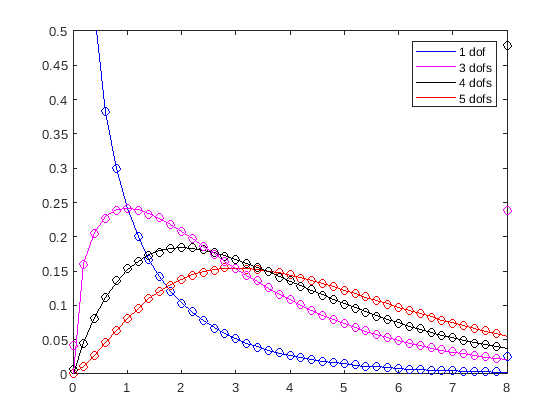


n  = 5;           % sample size
ns = 1000000;     % number of samples
d  = zeros(ns,1);
for i = 1:ns
  x = rand(n,1);           % data: (x,y)
  y = randn(n,1);
  X = [ones(n,1) x];       % least squares matrix
  w = X \ y;               % regression weights
  r = (w(1) + w(2)*x) - y; % residual vector
  d(i) = r'*r;             % residual sum of squares
end

% compute standardized histogram
c = 0:0.2:8;      % bin centers
f = hist(d,c)/ns/0.2;
plot(c,f,'mo');
hold on

% plot chi-squared distribution with 3 dofs
y = chi2pdf(c,3);
p3 = plot(c,y,'m-');

% plot legend for specific plots in specific order
legend([p1 p3 p4 p5], {'1 dof','3 dofs','4 dofs','5 dofs'});